% Step 1
clear;

% Define Constants
fc = 900e6;
Ts = 1e-3;
c = 3e8;
V = 25;
var_1 = 1;
sigma_1 = sqrt(var_1);
mean = 0;

% Step 2

% Calculate Normalized Doppler Frequency
fd_max = (V*fc)/c;
fd_norm = fd_max * Ts;

% Step 3

% Number Of PoinTs In Freq Domain Using Shaping Filter
M = 1000;
k_m = fd_norm*M;

% Step 4

% Sampling Interval
delta_f = 1 / (M*Ts);

% Step 5

% Generate 2 Random Guassian Vectors
X = sigma_1*randn(1,M);
Y = sigma_1*randn(1,M);

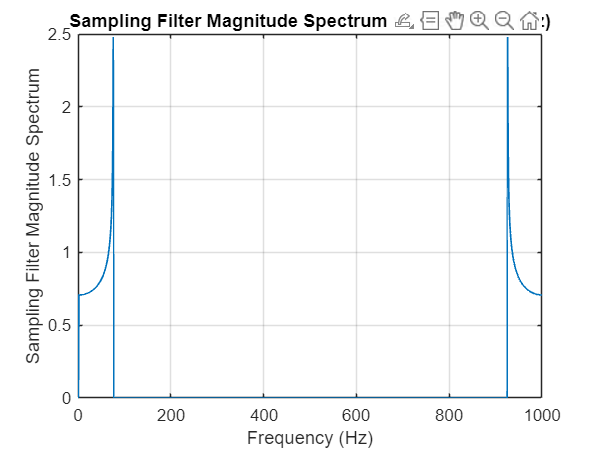

% Step 6

% Magnitude Response Of Shaping Filter
F = [];
for m = 1:M;

    if m == 1
        F(m) = 0;
    
    elseif m >= 2 && m <= k_m
        F(m) = sqrt(0.5/sqrt(1-((m-1)/(M*Ts*fd_max))^2));
    
    elseif m == k_m+1
        F(m) = sqrt((k_m/2)*((pi/2)-atan((k_m-1)/sqrt(2*k_m-1))));
    
    elseif m >= (k_m+2) && m <= (M-k_m)
        F(m) = 0;
    
    elseif m == (M-k_m+1)
        F(m) = sqrt((k_m/2)*((pi/2)-atan((k_m-1)/sqrt(2*k_m-1))));
    
    elseif m >= (M-k_m+2) && m <= m
        F(m) = sqrt(0.5/sqrt(1-((M-(m-1))/(M*Ts*fd_max))^2));

    end

end

figure;
plot(1:1000, F, LineWidth = 1);
xlabel('Frequency (Hz)');
ylabel('Sampling Filter Magnitude Spectrum');
title('Sampling Filter Magnitude Spectrum vs Frequency (Hz)');
grid on;

% Step 7 & 8

% Output Of Shaping Filter
filt_oup = [];
for m = 1:M
    filt_oup(m) = X(m)*F(m) - 1i*Y(m)*F(m);
end

% IFFT Of Output Of Shaping Filter
inv_filt_out = ifft(filt_oup, M);

% Step 9

% Sigma_2 and Var_2
var_2 = 0;
for m = 1:M
    var_2 = var_2 + (F(m) / M)^2;
end
var_2 = var_2 * var_1;
sigma_2 = sqrt(var_2);

% Scaling Factor
SF = 1 / (sigma_2*sqrt(2));

% Step 9.5

% IFFT Output Vector Multiplied By Scaling Factor
Z = inv_filt_out*SF;
Zi = real(Z);
Zq = imag(Z);
Pi = 0;
Pq = 0;

% Power Summation For Zi and Zq
for m = 1:M
    Pi = Pi + Zi(m)^2;
    Pq = Pq + Zq(m)^2;
end

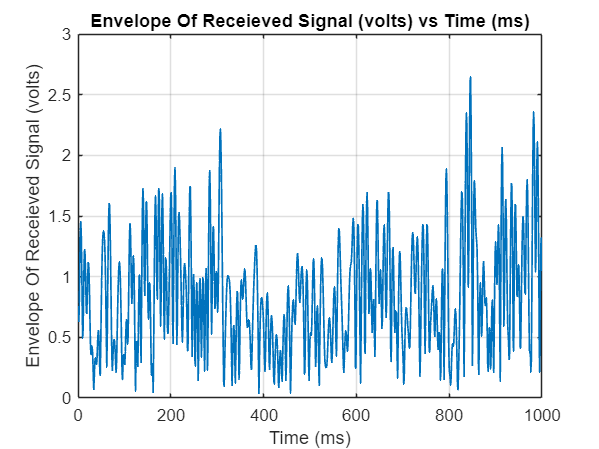

% Step 10

% Receieved Signal Envelope
R_m = [];
for m = 1:M
    R_m(m) = sqrt(Zi(m)^2 + Zq(m)^2);
end

figure;
plot(1:1000, R_m, LineWidth = 1);
xlabel('Time (ms)');
ylabel('Envelope Of Receieved Signal (volts)');
title('Envelope Of Receieved Signal (volts) vs Time (ms)');
grid on;

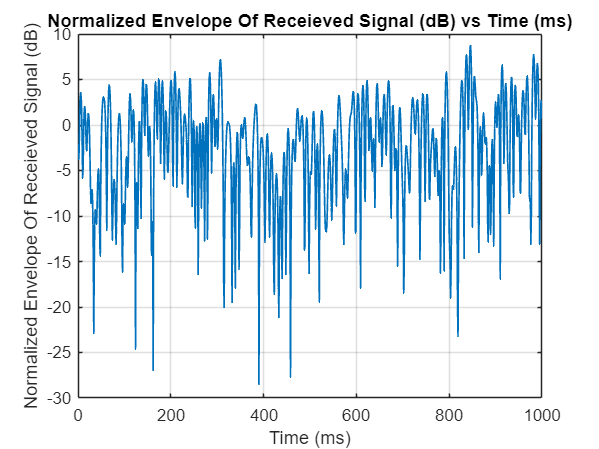


% Receieved Signal Envelope Normalized In dB
R_rms = 0;
for m = 1:M
    R_rms = R_rms + R_m(m)^2;
end

R_rms = sqrt(R_rms / M);

R_dB = 20*log10(R_m / R_rms);

figure;
plot(1:1000, R_dB, LineWidth = 1);
xlabel('Time (ms)');
ylabel('Normalized Envelope Of Receieved Signal (dB)');
title('Normalized Envelope Of Receieved Signal (dB) vs Time (ms)');
grid on;

% Step 11 & 12

% Average Power K = 1
P_avg = [];
P_avg(1) = (Pi + Pq) / M;

% Threshold Is Average Iteration
P_th = P_avg(1);       
N_out = 0;

% Loop Through M, Check For < Threshold
for m = 1:M
    P_inst = Zi(m)^2 + Zq(m)^2;
    if P_inst < P_th
        N_out = N_out + 1;
    end
end

P_out_sim(1) = N_out / M;

% Step 13+ In Other File